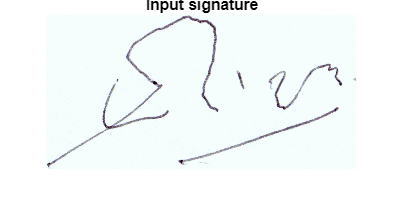

% Prompt the user to select an image from their PC
[filename, filepath] = uigetfile({'*.png;*.jpg;*.jpeg', 'Image files'}, 'Select an image');

% Check if the user canceled the selection
if isequal(filename, 0) || isequal(filepath, 0)
    disp('Image selection canceled.');
    return; % Exit the script if the user canceled the selection
end

% Load the selected image
input_image = imread(fullfile(filepath, filename));

%Display the real signature and the input signature
imshow(input_image)
title('Input signature')

real_sig=imshow("D:\Downloads\archive\sign_data\train\003\003_01.PNG")

real_sig =   Image with properties:

           CData: [109×541×3 uint8]
    CDataMapping: 'direct'

  Show all properties


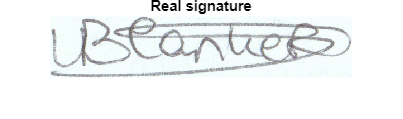

title('Real signature')


% Preprocess the input image
input_image = imresize(input_image, [100, 100]); % Resize to match training data size
input_image = rgb2gray(input_image); % Convert to grayscale if needed
input_vector = input_image(:); % Flatten the image into a vector

% Extract features (flatten the image into a vector)
input_features = double(input_vector); % Convert to double

% Make prediction using the trained SVM model
predicted_label = predict(SVMModel, input_features');

% Display the prediction result

if predicted_label == 0
    disp('The input signature is predicted to be forged.');
else
    disp('The input signature is predicted to be real.');
end

The input signature is predicted to be real.
